# System of Simultaneous Linear Equations

- Gauss Elimination

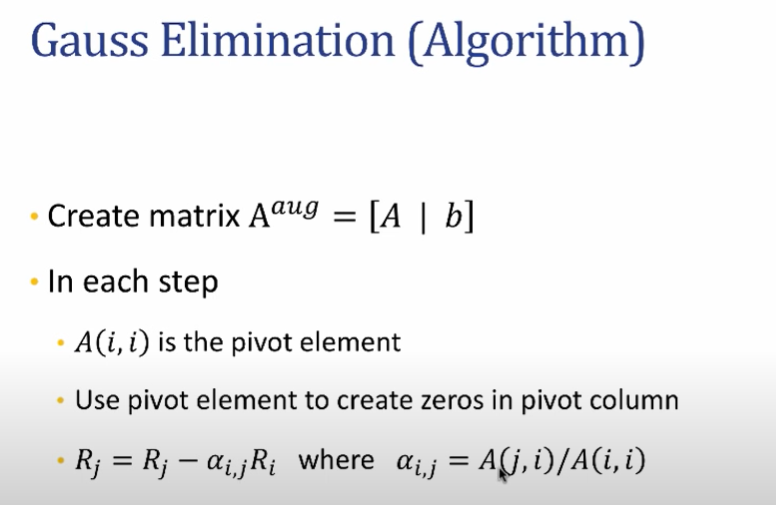

Note - Determinant of A should not be **zero**

clc;
clear;
format short;
A = [ 40+3i -10 -30; -10 30 -5; -30 -5 65 ];
B = [10; 0 ; 0];

if(det(A)==0)
    disp('Determinant is 0, so unable to proceed')
    return;
end

answer = A\B;

aug = [A,B]; % Augmented Matrix

n = length(A)

n = 3

for i = 1:n-1
    fprintf('i=%d,',i)
    for j = 1:(n-i)
        if(aug(i,i)==0)
            disp(' Divided by 0 Error was coming thats why, I returned from here ');
            return; % This is added 
        end
        alpha = aug(j+i,i)/aug(i,i);
        aug(j+i,:) = aug(j+i,:) - alpha*aug(i,:);
    end
end

i=1,i=2,


disp(aug); % Converted into upper triangular Matrix

  40.0000 + 3.0000i -10.0000 + 0.0000i -30.0000 + 0.0000i  10.0000 + 0.0000i
   0.0000 + 0.0000i  27.5140 + 0.1865i -12.4580 + 0.5594i   2.4860 - 0.1865i
   0.0000 - 0.0000i   0.0000 + 0.0000i  37.0000 + 2.2227i   8.5789 - 0.7019i




% Doing Backsubstitution

xvalues(1:length(A)) = 0; % Creates X values
xvalues = xvalues';
for i = 1:length(xvalues)
    index = length(xvalues)-i+1;
    xvalues(index) = (aug(index,end) - aug(index,index:length(xvalues))*xvalues(index:length(xvalues)))/aug(index,index);
end

disp('Final Values = ')

Final Values = 


disp(xvalues);

   0.4658 - 0.0664i
   0.1936 - 0.0276i
   0.2299 - 0.0328i



disp('Correct Ans = ');

Correct Ans = 


disp(answer);

   0.4658 - 0.0664i
   0.1936 - 0.0276i
   0.2299 - 0.0328i



## Some Issues with Gauss Elimination Method

- Division by Zero 

- Round off Errors

**Division by Zero**

This can happen if one of the diagonal elements become zero, in intermediate stage while on which the division was going on, so it will generate Division by Zero Error

**Round Off Errors**

## Gauss Jordan Method


for i=1:length(A)-1
    for j=i:length(A)-1
        % j as row
        % i as column
        fprintf('i=%d,j=%d\n',n-j,n-i+1);
        a = n-j;
        b = n-i+1;
        fprintf('--------------------------');
        
        disp(aug)
        

        alpha = aug(a,b)/aug(b,b);
        aug(a,:) = aug(a,:) - alpha*aug(b,:);
    end
    
end

i=2,j=3


--------------------------

   1.0000 + 2.0000i  -1.0000 + 2.0000i   2.0000 - 4.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.8000 - 0.6000i  -0.6000 + 1.2000i   4.0000 + 4.0000i
  -0.0000 - 0.0000i   0.0000 + 0.0000i  43.9512 + 1.5610i  -0.4878 - 4.3902i



i=1,j=3


--------------------------

   1.0000 + 2.0000i  -1.0000 + 2.0000i   2.0000 - 4.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   2.8000 - 0.6000i   0.0000 + 0.0000i   3.8720 + 3.9579i
  -0.0000 - 0.0000i   0.0000 + 0.0000i  43.9512 + 1.5610i  -0.4878 - 4.3902i



i=1,j=2


--------------------------

   1.0000 + 2.0000i  -1.0000 + 2.0000i   0.0000 + 0.0000i   0.4267 + 0.1402i
   0.0000 + 0.0000i   2.8000 - 0.6000i   0.0000 + 0.0000i   3.8720 + 3.9579i
  -0.0000 - 0.0000i   0.0000 + 0.0000i  43.9512 + 1.5610i  -0.4878 - 4.3902i




fprintf('--------------------------');

--------------------------

disp(aug)

   1.0000 + 2.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   4.7289 - 0.2900i
   0.0000 + 0.0000i   2.8000 - 0.6000i   0.0000 + 0.0000i   3.8720 + 3.9579i
  -0.0000 - 0.0000i   0.0000 + 0.0000i  43.9512 + 1.5610i  -0.4878 - 4.3902i




xvalues(1:length(A)) = 0;
xvalues = xvalues';
for i=1:n
    xvalues(i) = aug(i,end)/aug(i,i);
end

disp('Final Values = ')

Final Values = 


disp(xvalues);

   0.8298 - 1.9496i   1.0325 + 1.6348i  -0.0146 - 0.0994i



disp('Correct Ans = ');

Correct Ans = 


disp(answer);

   0.8298 - 1.9496i
   1.0325 + 1.6348i
  -0.0146 - 0.0994i

